Daten vorbereiten

imgSize = 224;   % [224 x 224 x 3] - Bilder

%Laden des Testdatensatzes
imDstrain = shuffle(imageDatastore(fullfile('Daten','Blumen','train'), ...
   'IncludeSubfolders',true, 'LabelSource','foldernames'));
tabulate(imDstrain.Labels);

      Value    Count   Percent
   Gattung1      353     10.44%
  Gattung10      293      8.66%
   Gattung2      466     13.78%
   Gattung3      350     10.35%
   Gattung4      310      9.17%
   Gattung5      454     13.42%
   Gattung6      247      7.30%
   Gattung7      300      8.87%
   Gattung8      278      8.22%
   Gattung9      331      9.79%


C = length(categories(imDstrain.Labels));

%% Aufteilung des Testdatensatzes in 80% Trainingsdaten, 20 % Validierungsdaten
[trainImDs, valImDs] = splitEachLabel(imDstrain,0.8,0.2,'randomized');


%Laden des Trainingsdatensatzes
testImDs = shuffle(imageDatastore(fullfile('Daten','Blumen','test'), ...
   'IncludeSubfolders',true, 'LabelSource','foldernames'));
tabulate(testImDs.Labels);

      Value    Count   Percent
   Gattung1       88     10.41%
  Gattung10       73      8.64%
   Gattung2      116     13.73%
   Gattung3       88     10.41%
   Gattung4       77      9.11%
   Gattung5      113     13.37%
   Gattung6       62      7.34%
   Gattung7       75      8.88%
   Gattung8       70      8.28%
   Gattung9       83      9.82%


Bilder anschauen

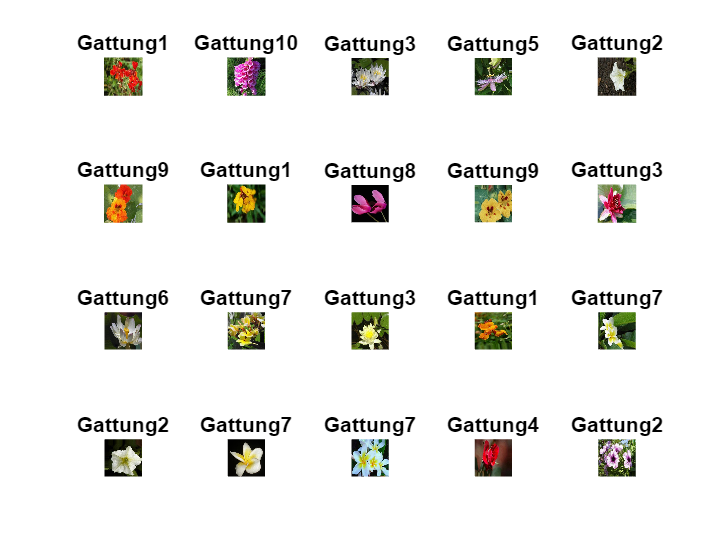

t = tiledlayout('flow'); % 4,5, 'TileSpacing','compact', 'Padding', 'compact');
for i = 1:20
   nexttile;
   [img, info] = trainImDs.read(); 
   imshow(img); 
   title(sprintf('%s', info.Label)); 
end

%googlenet laden
net = googlenet; 
inputSize = net.Layers(1).InputSize;
classNames = net.Layers(end).Classes; 

%% Daten für Googlenet Inputlayer
trainDsResized = augmentedImageDatastore(inputSize(1:2), trainImDs); 
valDsResized = augmentedImageDatastore(inputSize(1:2), valImDs); 
testDsResized = augmentedImageDatastore(inputSize(1:2), testImDs);   

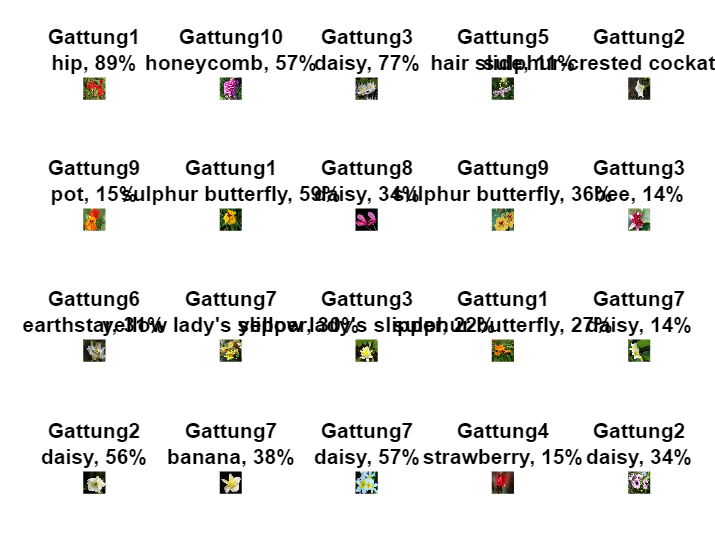



%% 4.2: Original-Googlenet auf die Daten anwenden
lbl = classify(net, trainDsResized);
tiledlayout(4,5, 'TileSpacing','compact', 'Padding', 'compact');
imgBatch= read(trainDsResized); 
for i = 1:20
   nexttile;
   img = imgBatch.input{i};
   [lbl, score] = classify(net, img); 
   imshow(img); 
   title({string(imgBatch.response(i)), sprintf('%s, %.f%%', string(lbl), 100* max(score))}); 
end


%% 4.3: Netz anpassen
lgraph = layerGraph(net); 
% die 3 hintersten Schichten entfernen
lgraph = removeLayers(lgraph, {'loss3-classifier', 'prob', 'output'});
% eigene Klassifizierungsschichten einbauen
lgraph = addLayers(lgraph, ...
   [fullyConnectedLayer(C, 'Name', 'myFC', ...
   'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10)
   softmaxLayer('Name', 'mySM')
   classificationLayer('Name', 'myClass')]);
lgraph = connectLayers(lgraph, 'pool5-drop_7x7_s1', 'myFC'); 


## Trainieren ohne Schichten einzufrieren und Fehler berechnen

lambda = 0.0001;
options = trainingOptions('adam', 'MaxEpochs', 500, 'L2Regularization', lambda, 'MiniBatchSize', 64, ['' ...
    'Plots'], 'training-progress', 'Shuffle', 'every-epoch', 'InitialLearnRate', 0.01, 'LearnRateSchedule', ...
    'piecewise', 'LearnRateDropPeriod', 25, 'LearnRateDropFactor', 0.3);
tic
netTransfer = trainNetwork(trainDsResized, ...
   lgraph,options);
toc
% Fehler berechnen
trainLblPred = classify(netTransfer, trainDsResized);
trainErr = mean(trainImDs.Labels ~= trainLblPred); 
testLblPred = classify(netTransfer, testDsResized);
testErr = mean(testImDs.Labels ~= testLblPred);

cmTest = confusionmat(testImDs.Labels, testLblPred);
confusionchart(cmTest, categories(testImDs.Labels), ...
   'ColumnSummary', 'column-normalized', 'RowSummary', 'row-normalized', ...
   'Title', sprintf('Testfehler: %.1f%%', 100*testErr));


%% Einfrieren der ersten drei Inception-Blöcke also der ersten 52 Schichten 
frozenLayers = lgraph.Layers; 
freezeIdx = 1:52; 
frozenLayers(freezeIdx) = freezeWeights(lgraph.Layers(freezeIdx));

'freezeWeights' is used in the following examples:
  Convert Classification Network into Regression Network
  Train Deep Learning Network to Classify New Images

lgraph2 =  createLgraphUsingConnections(frozenLayers, lgraph.Connections);

%% 4.5 Trainieren und Fehler berechnen
miniBatchSize = 64;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'LearnRateSchedule', 'piecewise', ...
    'InitialLearnRate',1e-3, ...
    'LearnRateDropPeriod', 1, ...
    'Shuffle','every-epoch', ...
    'Verbose',true, ...
    'Plots','none', ...
    'ValidationData',valDsResized, ...
    'ValidationFrequency', 10);
tic
netTransfer2 = trainNetwork(trainDsResized, ...
   lgraph2,options);
toc
% Fehler berechnen
trainLblPred = classify(netTransfer2, trainDsResized);
trainErr = mean(trainImDs.Labels ~= trainLblPred); 
testLblPred = classify(netTransfer2, testDsResized);
testErr = mean(testImDs.Labels ~= testLblPred);

cmTest = confusionmat(testImDs.Labels, testLblPred);
confusionchart(cmTest, categories(testImDs.Labels), ...
   'ColumnSummary', 'column-normalized', 'RowSummary', 'row-normalized', ...
   'Title', sprintf('Testfehler: %.1f%%', 100*testErr));


%Layer Analyse
analyzeNetwork(lgraph2);

%Einfrieren der ersten 141 Schichten 
frozenLayers = lgraph.Layers; 
freezeIdx = 1:141; 
frozenLayers(freezeIdx) = freezeWeights(lgraph.Layers(freezeIdx));
lgraph3 =  createLgraphUsingConnections(frozenLayers, lgraph.Connections);

%% Trainieren und Fehler berechnen
miniBatchSize = 64;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'LearnRateSchedule', 'piecewise', ...
    'InitialLearnRate',1e-3, ...
    'LearnRateDropPeriod', 1, ...
    'Shuffle','every-epoch', ...
    'Verbose',true, ...
    'Plots','none', ...
    'ValidationData',valDsResized, ...
    'ValidationFrequency', 10);
tic
netTransfer2 = trainNetwork(trainDsResized, ...
   lgraph2,options);
toc
% Fehler berechnen
trainLblPred = classify(netTransfer2, trainDsResized);
trainErr = mean(trainImDs.Labels ~= trainLblPred); 
testLblPred = classify(netTransfer2, testDsResized);
testErr = mean(testImDs.Labels ~= testLblPred);

cmTest = confusionmat(testImDs.Labels, testLblPred);
confusionchart(cmTest, categories(testImDs.Labels), ...
   'ColumnSummary', 'column-normalized', 'RowSummary', 'row-normalized', ...
   'Title', sprintf('Testfehler: %.1f%%', 100*testErr));
